# **MOBILE-ROBOT: LASER**

**Authors: Iván López Buira & Jose Garcia Torres**

**Group: 11-F**

## DATA

clear;
load('Sensor_Data.mat');
load('Encoder_Data.mat');


## PARAMETERS

s = 0.02;
Tf = 60.08;
r_w = 0.0947;
W = 0.52;
S = W/2;
t=(0:Ts:Tf-Ts)';

R_inc=diff(R_acu(:,2));
L_inc=diff(L_acu(:,2));
delta_x= (R_inc+L_inc)/2;
delta_psi= (R_inc-L_inc)/W;

## POSE INTEGRATION

theta = pi/16;
Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2);
Initial_orientation=-pi/2;
o=[];

x(1)=Initial_pose(1)+0.05;
y(1)=Initial_pose(2);
o(1)=Initial_orientation;

 for i=1:(length(t)-1)
    x(i+1)= x(i)+delta_x(i)*cos(o(i));
    y(i+1)= y(i)+delta_x(i)*sin(o(i));
    o(i+1)=o(i)+delta_psi(i);
 end

## MAP BUILDING

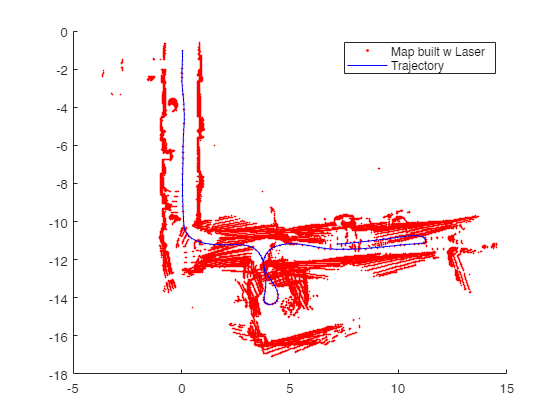

x2=[];
y2=[];
x2=[];
y2=[];

Pu = TLR Ppuntos

count = 1;
m = size(polar_laser_data);
for i=1:m(1)
    for j=1:(m(2)-1)
        if polar_laser_data(i, j)/1000 > 0
            alpha = (j-1) * 0.3515 * pi/180;
            if alpha <= 240/2
                alpha = o(20*i) + alpha - 122*pi/180;
            else alpha = o(20*i) - alpha - 122*pi/180;
        end
        x2(count) = x(20*i) + polar_laser_data(i, j)/1000 * cos(alpha);
        y2(count) = y(20*i) + polar_laser_data(i, j)/1000 * sin(alpha);
        count = count + 1;
        end
    end
end
figure
scatter(x2, y2, 0.5, '.','r')
hold on
plot(x,y,'b');
legend("Map built w Laser", "Trajectory");